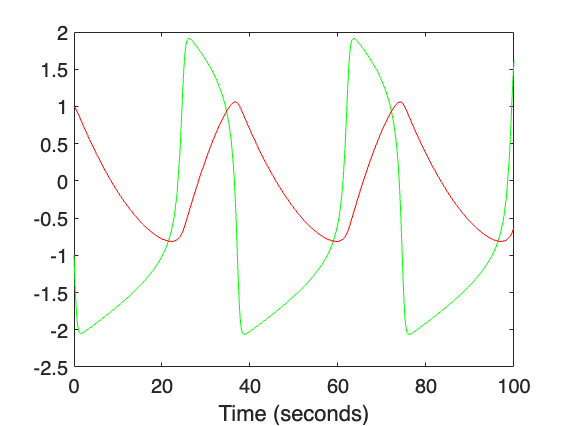

% 6.2.1 
epsilon = 0.08; % attachment rate, s^-1 uM^-1
a = 0.5; % unbinding rate s^-1
b = 0.2; % microMolar, concentration of transcription factor

initialCondition = [-1,1];

dvdt =@(v,w) v-v^3/3-w;
dwdt =@(v,w) epsilon*(v+a-b*w);

dxdt = @(t,x)[dvdt(x(1),x(2));
              dwdt(x(1),x(2))];

[T, X] = ode45(dxdt, [0.0,100], initialCondition);

% set up a figure
figure; clf; hold on; box on;
plot(T,X(:,1),'-g'); % green for v
plot(T,X(:,2),'-r'); % red for w
xlabel('Time (seconds)')

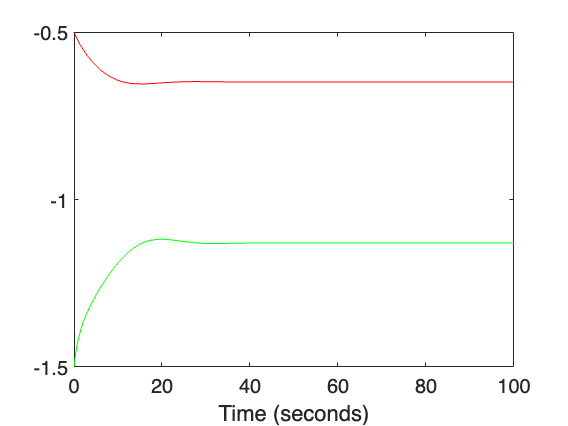

%6.2.2.1
epsilon = 0.08; % attachment rate, s^-1 uM^-1
a = 1; % unbinding rate s^-1
b = 0.2; % microMolar, concentration of transcription factor

initialCondition = [-1.5,-0.5];

dvdt =@(v,w) v-v^3/3-w;
dwdt =@(v,w) epsilon*(v+a-b*w);

dxdt = @(t,x)[dvdt(x(1),x(2));
              dwdt(x(1),x(2))];

[T, X] = ode45(dxdt, [0.0,100], initialCondition);

% set up a figure
figure; clf; hold on; box on;
plot(T,X(:,1),'-g'); % green for v
plot(T,X(:,2),'-r'); % red for w
xlabel('Time (seconds)')

steady state: v=-1.1,  w=-0.65

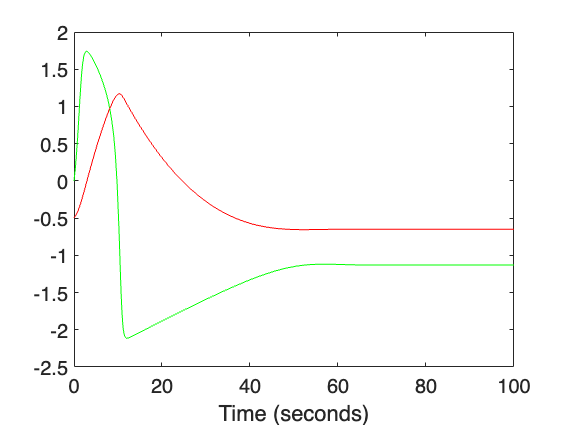

initialCondition = [-0,-0.5];

dvdt =@(v,w) v-v^3/3-w;
dwdt =@(v,w) epsilon*(v+a-b*w);

dxdt = @(t,x)[dvdt(x(1),x(2));
              dwdt(x(1),x(2))];

[T, X] = ode45(dxdt, [0.0,100], initialCondition);

% set up a figure
figure; clf; hold on; box on;
plot(T,X(:,1),'-g'); % green for v
plot(T,X(:,2),'-r'); % red for w
xlabel('Time (seconds)')

steady state:  v=-1.11, w=-0.65

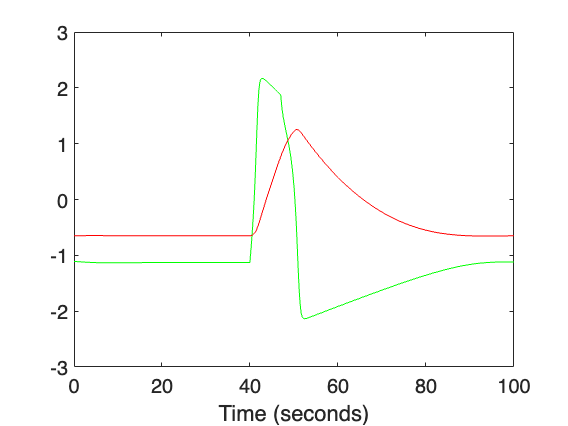

% 6.2.3 single cell current
epsilon = 0.08; % attachment rate, s^-1 uM^-1
a = 1; % unbinding rate s^-1
b = 0.2; % microMolar, concentration of transcription factor

initialCondition = [-1.11,-0.65];

I0 = 1.0;
tStart = 40;
tStop = 47;
I =@(t) I0*(t>tStart).*(t<tStop);

dvdt =@(v,w) v-v^3/3-w;
dwdt =@(v,w) epsilon*(v+a-b*w);

dxdt = @(t,x)[dvdt(x(1),x(2))+I(t);
              dwdt(x(1),x(2))];

[T, X] = ode45(dxdt, [0,100], initialCondition);

% set up a figure
figure; clf; hold on; box on;
plot(T,X(:,1),'-g'); % green for v
plot(T,X(:,2),'-r'); % red for w
xlabel('Time (seconds)')

    "cell"    "1"



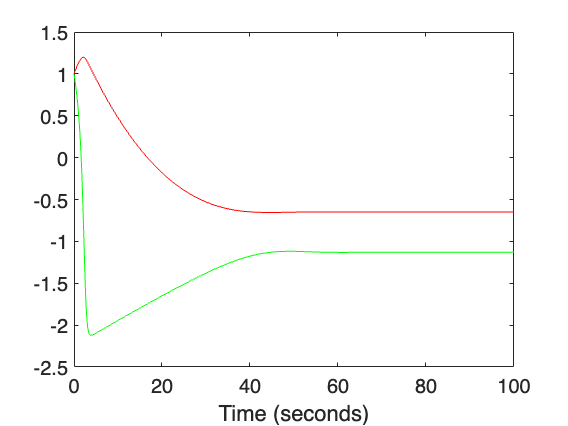

    "cell"    "2"



    "cell"    "3"



    "cell"    "4"



    "cell"    "5"



    "cell"    "6"



    "cell"    "7"



    "cell"    "8"



    "cell"    "9"



    "cell"    "10"



%6.2.4 multiple cell current
% no injection current
clear

epsilon = 0.08; % attachment rate, s^-1 uM^-1
a = 1; % unbinding rate s^-1
b = 0.2; % microMolar, concentration of transcription factor

%initialCondition = [repmat(-1.11,1,10),repmat(-0.65,1,10)];
initialCondition = ones(20,1);
D=0.9;

dvdt =@(v,w) v-v.^3/3-w;
dwdt =@(v,w) epsilon*(v+a-b*w);

dxdt = @(t,x)[dvdt(x(1:10),x(11:20))+D*(x([10,1:9])+x([2:10,1])-2*x(1:10));
              dwdt(x(1:10),x(11:20))];

[T, X] = ode45(dxdt, [0.0,100], initialCondition);

% set up a figure

for i=1:10 
    disp(["cell",i]);
    figure; clf; hold on; box on;
    plot(T,X(:,i),'-g'); % green for v1
    plot(T,X(:,i+10),'-r'); % red for w1
    xlabel('Time (seconds)')
end 

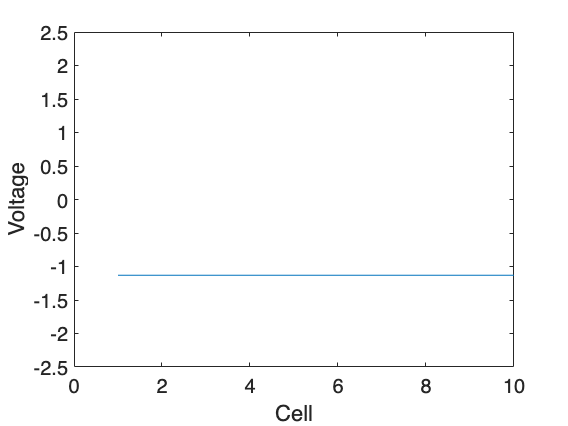


% movie for voltage in all ten cells
for nt=1:numel(T)
              figure(5); clf; hold on; box on;
              plot(X(nt,1:10));
              set(gca,'ylim', [-2.5,2.5])
              xlabel('Cell');
              ylabel('Voltage')
              drawnow;
end

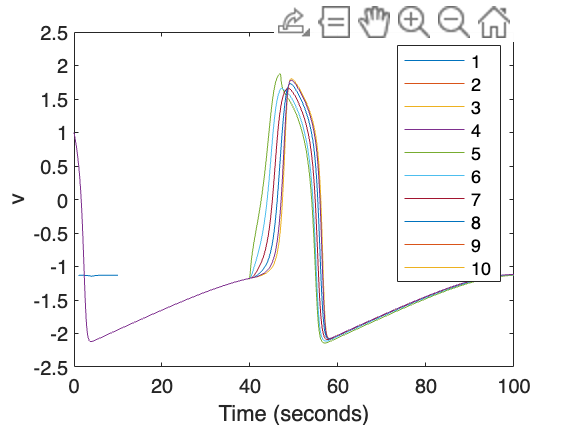

%current injection to cell 4
%initialCondition = [repmat(-1.11,1,10),repmat(-0.65,1,10)];
initialCondition = ones(20,1);
I0 = 1.0;
tStart = 40;
tStop = 47;
I =@(t) I0*(t>tStart).*(t<tStop);

dxdt = @(t,x)[dvdt(x(1:10),x(11:20))+[zeros(3,1);I(t);zeros(6,1)]+D*(x([10,1:9])+x([2:10,1])-2*x(1:10));
              dwdt(x(1:10),x(11:20))];

[T, X] = ode45(dxdt, [0.0,100], initialCondition);

% set up a figure

for i=1:10 
    plot(T,X(:,i)); %  v
end 
xlabel('Time (seconds)')
ylabel("v")
legend(string(1:10));

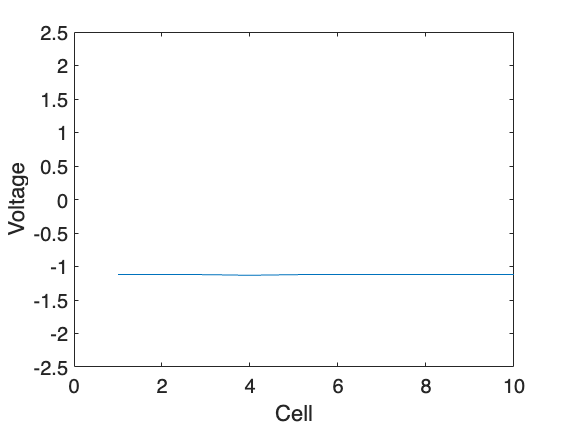



% movie for voltage in all ten cells
for nt=1:numel(T)
              figure(5); clf; hold on; box on;
              plot(X(nt,1:10));
              set(gca,'ylim', [-2.5,2.5])
              xlabel('Cell');
              ylabel('Voltage')
              drawnow;
end